#     Diskret Stokastisk

## Eksempel 1

**Formel for diskret CDF = **

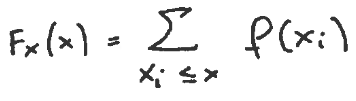

% Det vil sige:
% Fx(x=-3) == 1/7;
% Fx(x=0) == Fx(x=-3) + Fx(x=0) == 1/7 + 1/7
% Osv.
syms x
y = piecewise( x < -3, 0, ...
              -3 <= x < 0, 1/7, ...
              0 <= x < 2, 2/7, ...
              2 <= x < 4, 3/7, ...
              4 <= x < 7, 4/7, ...
              7 <= x < 10, 5/7, ...
              10 <= x < 12, 6/7, ...
              12 <= x, 7/7)

$$y = \left\{ \begin{array}{cl} 0 & \text{ if }x<-3\\ \frac{1}{7} & \text{ if }x\in \left[-3,0\right)\\ \frac{2}{7} & \text{ if }x\in \left[0,2\right)\\ \frac{3}{7} & \text{ if }x\in \left[2,4\right)\\ \frac{4}{7} & \text{ if }x\in \left[4,7\right)\\ \frac{5}{7} & \text{ if }x\in \left[7,10\right)\\ \frac{6}{7} & \text{ if }x\in \left[10,12\right)\\ 1 & \text{ if }12\leq x \end{array}\right.$$

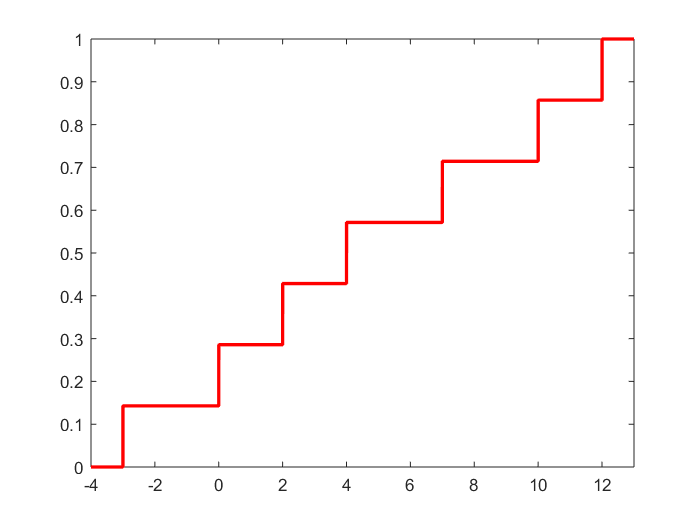

fplot(y, [-4, 13],'-r','LineWidth',2)

## Eksempel 2

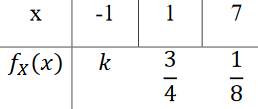

% Diskret CDF = Summen af alle værdier af fx skal give 1
% Plot
clearvars
close all
syms x
y = piecewise(x < -1, 0,-1<=x<1,1/8,1<=x<7,7/8,7<=x, 1)

$$y = \left\{ \begin{array}{cl} 0 & \text{ if }x<-1\\ \frac{1}{8} & \text{ if }x\in \left[-1,1\right)\\ \frac{7}{8} & \text{ if }x\in \left[1,7\right)\\ 1 & \text{ if }7\leq x \end{array}\right.$$

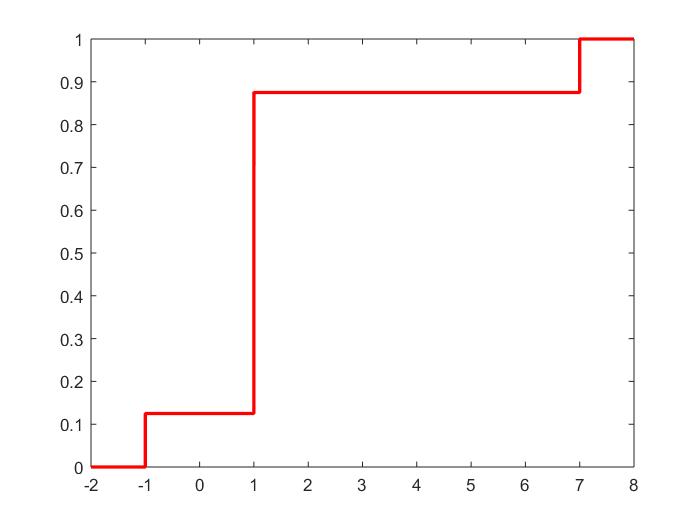

fplot(y,[-2,8], '-r','LineWidth',2)

# Kontinuert Stokastisk

## Eksempel 1

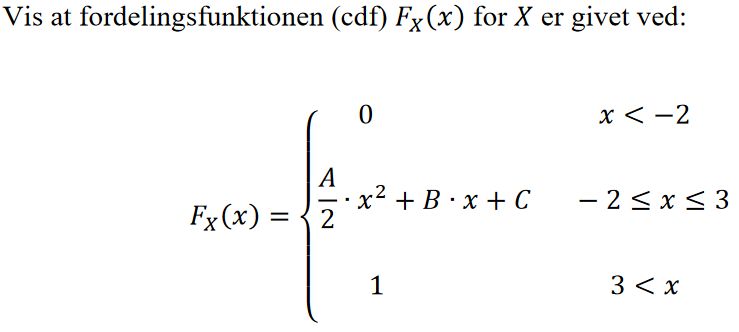

## pdf = 

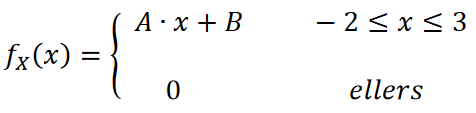

clearvars
close all
% Antagelser
% A = -2/25; B = 6/25; C = 16/25;
% Finder kun CDF For intervallet -2 til 3
% Da alt under -2 er 0, og alt over 3 er 1
syms x A B C
% CDF = integrale af pdf
pdf = A*x+B;
cdf = int(pdf) % Svaret er lidt forkert. Den tager ikke højde for regnereglerne omkring integration

$$cdf = \frac{A\,x^{2}}{2}+B\,x$$

% Svaret mangler + C, da konstanter er ligegyldige, men den skal med i det afleverede materiale.
